# XTD_A4: Cross Epoch Decodability

% load('.\XTD_WT_PI_PO_RawLFP.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_All_PO_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_DL_PI_PO.mat');

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);
%#ok<*UNRCH>
rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);

objTimeVect = mlb.obsvTimeVect-mlb.obsvTimeVect(1);


## Compile Data

trInt_DecPPF = cell(mlb.seqLength, length(fileDirs));
trIntCON_DecPPF = cell(mlb.seqLength, length(fileDirs));
trIntCON2_DecPPF = cell(mlb.seqLength, length(fileDirs));
trInt_TstTrl = cell(mlb.seqLength, length(fileDirs));
trIntCON_TstTrl = cell(mlb.seqLength, length(fileDirs));

trPre_DecPst = cell(mlb.seqLength, length(fileDirs));
trPst_DecPre = cell(mlb.seqLength, length(fileDirs));

trTrl_DecPPF = cell(mlb.seqLength, length(fileDirs));
trTrl_DecPPFcon = cell(mlb.seqLength, length(fileDirs));
trTrl_TstPPF = cell(mlb.seqLength, length(fileDirs));
trTrl_TstPPFcon = cell(mlb.seqLength, length(fileDirs));

trTrl_DecInt = cell(mlb.seqLength, length(fileDirs));
trTrl_DecIntCON = cell(mlb.seqLength, length(fileDirs));
trTrl_TstInt = cell(mlb.seqLength, length(fileDirs));
trTrl_TstIntCON = cell(mlb.seqLength, length(fileDirs));

for ani = 1:length(fileDirs)
    for pos = 1:mlb.seqLength
        % Extract Variables
%         curPos_D = xtd_D{pos,pos,ani};
        curPos_D = xtd_HR{pos,pos,ani};
        if pos~=1
%             prevPos_D = xtd_D{pos,pos-1,ani};
            prevPos_D = xtd_HR{pos,pos-1,ani};
        else
            prevPos_D = nan(size(curPos_D));
        end
        if pos~=mlb.seqLength
%             nextPos_D = xtd_D{pos,pos+1,ani};
            nextPos_D = xtd_HR{pos,pos+1,ani};
        else
            nextPos_D = nan(size(curPos_D));
        end
        if sum(pos~=[1,mlb.seqLength]) == 2
%             othrPos_D = xtd_D{pos,setxor(1:mlb.seqLength, [pos-1,pos,pos+1]),ani};
            othrPos_D = xtd_HR{pos,setxor(1:mlb.seqLength, [pos-1,pos,pos+1]),ani};
        else
            othrPos_D = nan(size(curPos_D));
        end
        curPos_TrialMask = mask_Trial{pos,ani};
        curPos_IntPreMask = mask_PreInt{pos,ani};
        curPos_IntPreMaskCON = mask_PreIntCON{pos,ani};
        curPos_IntPstMask = mask_PstInt{pos,ani};
        curPos_IntPstMaskCON = mask_PstIntCON{pos,ani};
        if strcmp(alignment{1}, 'PokeIn')
            curPos_IntMask = curPos_IntPreMask;
            curPos_IntMaskCON = curPos_IntPreMaskCON;
        else
            curPos_IntMask = curPos_IntPstMask;
            curPos_IntMaskCON = curPos_IntPstMaskCON;
        end
        % Create Trial Variables
        curTrl_trInt_DecPPF = nan(length(mlb.obsvTimeVect),size(curPos_D,3),4);
        curTrl_trIntCON_DecPPF = nan(length(mlb.obsvTimeVect),size(curPos_D,3),4);
        curTrl_trIntCON2_DecPPF = nan(length(mlb.obsvTimeVect),size(curPos_D,3),4);
        curTrl_trInt_TstTrl = nan(3,size(curPos_D,3));
        curTrl_trIntCON_TstTrl = nan(3,size(curPos_D,3));

        curTrl_trPre_TstPst = nan(3,size(curPos_D,3));
        curTrl_trPst_TstPre = nan(3,size(curPos_D,3));

        curTrl_trTrl_DecPPF = nan(length(mlb.obsvTimeVect),size(curPos_D,3),3);
        curTrl_trTrl_DecPPFcon = nan(length(mlb.obsvTimeVect),size(curPos_D,3),3);
        curTrl_trTrl_TstPPF = nan(3,size(curPos_D,3));
        curTrl_trTrl_TstPPFcon = nan(3,size(curPos_D,3));

        curTrl_trTrl_DecInt = nan(length(mlb.obsvTimeVect),size(curPos_D,3),2);
        curTrl_trTrl_DecIntCON = nan(length(mlb.obsvTimeVect),size(curPos_D,3),2);
        curTrl_trTrl_TstInt = nan(2,size(curPos_D,3));
        curTrl_trTrl_TstIntCON = nan(2,size(curPos_D,3));
        % Analyze Trials
        for trl = 1:size(curPos_D,3)
            % Define Trial Data
            curTrl_D = curPos_D(:,:,trl);
            curTrl_Dprev = prevPos_D(:,:,trl);
            curTrl_Dnxt = nextPos_D(:,:,trl);
            curTrl_Dothr = othrPos_D(:,:,trl);
            % Collect Data - Interval Trained Models
            curTrl_trInt_DecPPF(:,trl,:) = cat(3,mean(curTrl_Dprev(:,curPos_IntMask(:,trl)), 2, 'omitnan'),...
                mean(curTrl_D(:,curPos_IntMask(:,trl)), 2, 'omitnan'),...
                mean(curTrl_Dnxt(:,curPos_IntMask(:,trl)), 2, 'omitnan'),...
                mean(curTrl_Dothr(:,curPos_IntMask(:,trl)), 2, 'omitnan'));
            curTrl_trIntCON_DecPPF(:,trl,:) = cat(3,mean(curTrl_Dprev(:,curPos_IntMaskCON(:,trl)), 2, 'omitnan'),...
                mean(curTrl_D(:,curPos_IntMaskCON(:,trl)), 2, 'omitnan'),...
                mean(curTrl_Dnxt(:,curPos_IntMaskCON(:,trl)), 2, 'omitnan'),...
                mean(curTrl_Dothr(:,curPos_IntMaskCON(:,trl)), 2, 'omitnan'));
            if strcmp(alignment{1}, 'PokeIn')
                curPos_IntMaskCON2 = find(curPos_IntMask(:,trl),1,'first');
            else
                curPos_IntMaskCON2 = find(curPos_IntMask(:,trl),1,'last');
            end
            curTrl_trIntCON2_DecPPF(:,trl,:) = cat(3,curTrl_Dprev(:,curPos_IntMaskCON2),...
                curTrl_D(:,curPos_IntMaskCON2),...
                curTrl_Dnxt(:,curPos_IntMaskCON2),...
                curTrl_Dothr(:,curPos_IntMaskCON2));
            curTrl_trInt_TstTrl(:,trl) = [mean(curTrl_Dprev(curPos_TrialMask(:,trl),curPos_IntMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_D(curPos_TrialMask(:,trl),curPos_IntMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_Dnxt(curPos_TrialMask(:,trl),curPos_IntMask(:,trl)), 'all', 'omitnan')];
            curTrl_trIntCON_TstTrl(:,trl) = [mean(curTrl_Dprev(curPos_TrialMask(:,trl), curPos_IntMaskCON(:,trl)), 'all', 'omitnan');...
                mean(curTrl_D(curPos_TrialMask(:,trl),curPos_IntMaskCON(:,trl)), 'all','omitnan');...
                mean(curTrl_Dnxt(curPos_TrialMask(:,trl),curPos_IntMaskCON(:,trl)), 'all', 'omitnan')];
            % Collect Data - Non-Overlapping Interval Train/Test
            curTrl_trPre_TstPst(:,trl) = [mean(curTrl_Dprev(curPos_IntPstMask(:,trl), curPos_IntPreMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_D(curPos_IntPstMask(:,trl), curPos_IntPreMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_Dnxt(curPos_IntPstMask(:,trl), curPos_IntPreMask(:,trl)), 'all', 'omitnan')];
            curTrl_trPst_TstPre(:,trl) = [mean(curTrl_Dprev(curPos_IntPreMask(:,trl), curPos_IntPstMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_D(curPos_IntPreMask(:,trl), curPos_IntPstMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_Dnxt(curPos_IntPreMask(:,trl), curPos_IntPstMask(:,trl)), 'all', 'omitnan')];

            % Collect Data - Trial Trained Models
            if strcmp(alignment{1}, 'PokeIn')
                curTrl_trTrl_DecPPF(1:sum(curPos_TrialMask(:,trl)),trl,:) = cat(3,mean(curTrl_Dprev(curPos_IntMask(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan'),...
                    mean(curTrl_D(curPos_IntMask(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan'),...
                    mean(curTrl_Dnxt(curPos_IntMask(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan'));
                curTrl_trTrl_DecPPFcon(1:sum(curPos_TrialMask(:,trl)),trl,:) = cat(3,mean(curTrl_Dprev(curPos_IntMaskCON(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan'),...
                    mean(curTrl_D(curPos_IntMaskCON(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan'),...
                    mean(curTrl_Dnxt(curPos_IntMaskCON(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan'));
            else
                curTrl_trTrl_DecPPF(end-sum(curPos_TrialMask(:,trl))+1:end,trl,:) = cat(3,mean(curTrl_Dprev(curPos_IntMask(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan'),...
                    mean(curTrl_D(curPos_IntMask(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan'),...
                    mean(curTrl_Dnxt(curPos_IntMask(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan'));
                curTrl_trTrl_DecPPFcon(end-sum(curPos_TrialMask(:,trl))+1:end,trl,:) = cat(3,mean(curTrl_Dprev(curPos_IntMaskCON(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan'),...
                    mean(curTrl_D(curPos_IntMaskCON(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan'),...
                    mean(curTrl_Dnxt(curPos_IntMaskCON(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan'));
            end
            curTrl_trTrl_TstPPF(:,trl) =  [mean(curTrl_Dprev(curPos_IntMask(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_D(curPos_IntMask(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_Dnxt(curPos_IntMask(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan')];
            curTrl_trTrl_TstPPFcon(:,trl) = [mean(curTrl_Dprev(curPos_IntMaskCON(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_D(curPos_IntMaskCON(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_Dnxt(curPos_IntMaskCON(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan')];

            temp_trTrl_DecPre = mean(curTrl_D(curPos_IntPreMask(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan');
            temp_trTrl_DecPst = mean(curTrl_D(curPos_IntPstMask(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan');
            temp_trTrl_DecPreCON = mean(curTrl_D(curPos_IntPreMaskCON(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan');
            temp_trTrl_DecPstCON = mean(curTrl_D(curPos_IntPstMaskCON(:,trl),curPos_TrialMask(:,trl)), 1, 'omitnan');

            if strcmp(alignment{1}, 'PokeIn')
                curTrl_trTrl_DecInt(1:sum(curPos_TrialMask(:,trl)),trl,:) = cat(3,temp_trTrl_DecPre',temp_trTrl_DecPst');
                curTrl_trTrl_DecIntCON(1:sum(curPos_TrialMask(:,trl)),trl,:) = [temp_trTrl_DecPreCON',temp_trTrl_DecPstCON'];
            else
                curTrl_trTrl_DecInt(end-sum(curPos_TrialMask(:,trl))+1:end,trl,:) = [temp_trTrl_DecPre',temp_trTrl_DecPst'];
                curTrl_trTrl_DecIntCON(end-sum(curPos_TrialMask(:,trl))+1:end,trl,:) = [temp_trTrl_DecPreCON',temp_trTrl_DecPstCON'];
            end

            curTrl_trTrl_TstInt(:,trl) = [mean(curTrl_D(curPos_IntPreMask(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan');...
                mean(curTrl_D(curPos_IntPstMask(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan')];
            curTrl_trTrl_TstIntCON(:,trl) = [mean(curTrl_D(curPos_IntPreMaskCON(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan');...
                 mean(curTrl_D(curPos_IntPstMaskCON(:,trl),curPos_TrialMask(:,trl)), 'all', 'omitnan')];
        end
        trInt_DecPPF{pos,ani} = curTrl_trInt_DecPPF;
        trIntCON_DecPPF{pos,ani} = curTrl_trIntCON_DecPPF;
        trIntCON2_DecPPF{pos,ani} = curTrl_trIntCON2_DecPPF;
        trInt_TstTrl{pos,ani} = curTrl_trInt_TstTrl;
        trIntCON_TstTrl{pos,ani} = curTrl_trIntCON_TstTrl;

        trPre_DecPst{pos,ani} = curTrl_trPre_TstPst;
        trPst_DecPre{pos,ani} = curTrl_trPst_TstPre;

        trTrl_DecPPF{pos,ani} = curTrl_trTrl_DecPPF;
        trTrl_DecPPFcon{pos,ani} = curTrl_trTrl_DecPPFcon;
        trTrl_TstPPF{pos,ani} = curTrl_trTrl_TstPPF;
        trTrl_TstPPFcon{pos,ani} = curTrl_trTrl_TstPPFcon;

        trTrl_DecInt{pos,ani} = curTrl_trTrl_DecInt;
        trTrl_DecIntCON{pos,ani} = curTrl_trTrl_DecIntCON;
        trTrl_TstInt{pos,ani} = curTrl_trTrl_TstInt;
        trTrl_TstIntCON{pos,ani} = curTrl_trTrl_TstIntCON;
    end
end

trialLIGHTlat = lat_PrtLight(2:end,:)';
% trialLIGHTlat = cell2mat(trialLIGHTlat(:)');
trialPIlat = lat_TrlStart(:);
% trialPIlat = cell2mat(trialPIlat(:)');
trialSIGlat = lat_RwdSig(:);
% trialSIGlat = cell2mat(trialSIGlat(:)');
trialPOlat = lat_TrlEnd(:);
% trialPOlat = cell2mat(trialPOlat(:)');
trialRWDlat = lat_Rwd(:);
% trialRWDlat = cell2mat(trialRWDlat(:)');
nxtTrlLats = lat_NextTrl(:);
% nxtTrlLats = cell2mat(nxtTrlLats(:)');
prevTrlLats = lat_PrevTrl(:);
% prevTrlLats = cell2mat(prevTrlLats(:)');

if strcmp(alignment{1}, 'PokeIn')
    outSeqPokeDurs = cell2mat(cellfun(@(a){[a([a.TranspositionDistance]~=0 & [a.Performance]==1).PokeDuration]}, xtd_TrialInfo_FULL));
elseif strcmp(alignment{1}, 'PokeOut')
    outSeqPokeDurs = cell2mat(cellfun(@(a){[a([a.TranspositionDistance]~=0 & [a.Performance]==1).TargetDuration]-[a([a.TranspositionDistance]~=0 & [a.Performance]==1).PokeDuration]}, xtd_TrialInfo_FULL));
elseif strcmp(alignment{1}, 'FrontReward')
    outSeqPokeDurs = cell2mat(cellfun(@(a){[a([a.TranspositionDistance]~=0 & [a.Performance]==1).TargetDuration]-[a([a.TranspositionDistance]~=0 & [a.Performance]==1).PokeDuration] + 0.25}, xtd_TrialInfo_FULL));
end

## Plot Interval Training - Decode Past/Present/Future

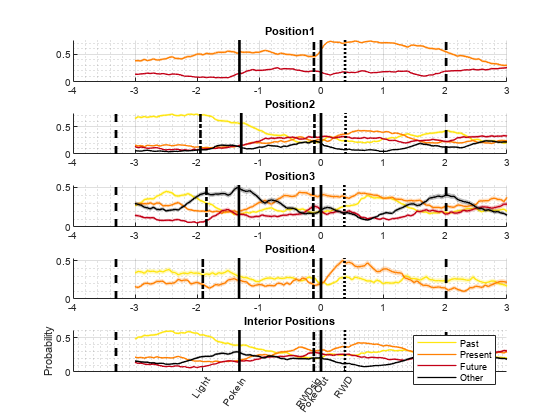

cur_Dec = trInt_DecPPF;
cur_Dec = trIntCON_DecPPF;
cur_Dec = trIntCON2_DecPPF;
figure;
sps = nan(1,mlb.seqLength+1);
for pos = 1:mlb.seqLength
    curPos_IntPPF = cell2mat(cur_Dec(pos,:));
    sps(pos) = subplot(mlb.seqLength+1,1,pos);
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, curPos_IntPPF(:,:,1), 2, 0, mlb.PPFcolors(1,:));
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, curPos_IntPPF(:,:,2), 2, 0, mlb.PPFcolors(2,:));
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, curPos_IntPPF(:,:,3), 2, 0, mlb.PPFcolors(3,:));
    mlb.PlotMeanVarLine(mlb.obsvTimeVect, curPos_IntPPF(:,:,4), 2, 0, 'k');
    if pos~=1
        plot(repmat(median(cell2mat(lat_PrtLight(pos,:))), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
        plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    plot(repmat(median(cell2mat(lat_TrlStart(pos,:))), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_RwdSig(pos,:))), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_TrlEnd(pos,:))), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_Rwd(pos,:))), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
    if strcmp(endTrialBound, 'RWD')
        plot( repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    title(sprintf('Position%i',pos));
    grid on;
    grid minor;
end

temp_Dec = cur_Dec;
tit = 'All Trials';
temp_Dec([1,mlb.seqLength],:) = []; tit = 'Interior Positions';
temp_Dec = cell2mat(temp_Dec(:)');
p=nan(1,4);
sps(end) = subplot(mlb.seqLength+1,1,mlb.seqLength+1);
p(1) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, temp_Dec(:,:,1), 2, 0, mlb.PPFcolors(1,:));
p(2) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, temp_Dec(:,:,2), 2, 0, mlb.PPFcolors(2,:));
p(3) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, temp_Dec(:,:,3), 2, 0, mlb.PPFcolors(3,:));
p(4) = mlb.PlotMeanVarLine(mlb.obsvTimeVect, temp_Dec(:,:,4), 2, 0, 'k');
plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
if strcmp(endTrialBound, 'RWD')
    plot(repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
elseif strcmp(endTrialBound, 'PO')
    plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
elseif strcmp(endTrialBound, 'RS')
    plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
end
plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
set(gca,'xtick', [median(cell2mat(trialLIGHTlat(:)')),...
    median(cell2mat(trialPIlat(:)')),...
    median(cell2mat(trialSIGlat(:)')),...
    median(cell2mat(trialPOlat(:)')),...
    median(cell2mat(trialRWDlat(:)'))], 'xticklabels', [{'Light'}, {'PokeIn'}, {'RWDsig'}, {'PokeOut'}, {'RWD'}], 'Xticklabelrotation',55);
title(tit);
legend(p, [{'Past'}, {'Present'}, {'Future'}, {'Other'}]);
ylabel('Probability');
grid on;
grid minor;
linkaxes(sps,'x');

## Analyze Interval Training - Decode Past/Present/Future

trWinStrt = mlb.obsvTimeVect(find(mlb.obsvTimeVect>median(cell2mat(trialLIGHTlat(:)')),1,'first'));
trWinEnd = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(cell2mat(trialRWDlat(:)')),1,'last'));
trWinLog = mlb.obsvTimeVect>trWinStrt & mlb.obsvTimeVect<trWinEnd;

timeStrs = arrayfun(@(a){sprintf('T%i',a)}, 1:sum(trWinLog));
rmTable = table('Size', [size(temp_Dec,2)*size(temp_Dec,3), sum(trWinLog)+1],...
    'VariableTypes', [{'categorical'}, repmat({'double'}, [1,sum(trWinLog)])],...
    'VariableNames', [{'Time'}, timeStrs]);
tpMeas = table((1:sum(trWinLog))', 'VariableNames', {'Time_Bins'});

prDec = temp_Dec(trWinLog,:,1);
crDec = temp_Dec(trWinLog,:,2);
ftDec = temp_Dec(trWinLog,:,3);
othDec = temp_Dec(trWinLog,:,4);

rmTable.Time = [repmat({'Pre'}, [size(prDec,2),1]);...
    repmat({'Cur'}, [size(crDec,2),1]);...
    repmat({'Pst'}, [size(crDec,2),1]);...
    repmat({'Othr'}, [size(crDec,2),1])];
for t = 1:length(timeStrs)
    rmTable.(timeStrs{t}) = [prDec(t,:), crDec(t,:), ftDec(t,:), othDec(t,:)]';
end

ppfRM = fitrm(rmTable, sprintf('%s-%s~Time', timeStrs{1}, timeStrs{end}), 'WithinDesign', tpMeas);
ppfRtable = ranova(ppfRM)

ppfRtable = 3×8 table
                               SumSq        DF        MeanSq          F        pValue     pValueGG       pValueHF       pValueLB 
                             __________    _____    __________    _________    ______    ___________    ___________    __________

    (Intercept):Time_Bins    1.1135e-26       43    2.5896e-28    3.322e-27       1                1              1             1
    Time:Time_Bins               346.27      129        2.6842       34.434       0      1.0894e-233    1.9938e-235    1.2837e-21
    Error(Time_Bins)             5845.9    74992      0.077953                                                                   


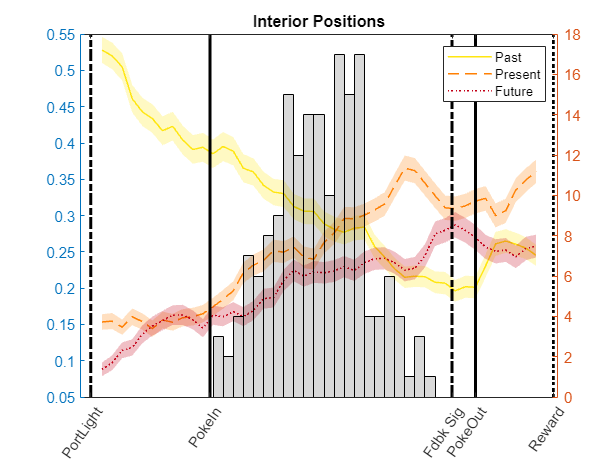

figure;
yyaxis right
histogram(outSeqPokeDurs+median(cell2mat(trialPIlat(:)')), mlb.obsvTimeVect(trWinLog), 'FaceColor', 'k', 'FaceAlpha', 0.15);
yyaxis left
p = nan(1,3);
p(1) = mlb.PlotMeanVarLine(mlb.obsvTimeVect(trWinLog), prDec, 2, 0, mlb.PPFcolors(1,:));
p(2) = mlb.PlotMeanVarLine(mlb.obsvTimeVect(trWinLog), crDec, 2, 0, mlb.PPFcolors(2,:));
p(3) = mlb.PlotMeanVarLine(mlb.obsvTimeVect(trWinLog), ftDec, 2, 0, mlb.PPFcolors(3,:));
plot(repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
set(gca,'xtick', [median(cell2mat(trialLIGHTlat(:)')),...
    median(cell2mat(trialPIlat(:)')),...
    median(cell2mat(trialSIGlat(:)')),...
    median(cell2mat(trialPOlat(:)')),...
    median(cell2mat(trialRWDlat(:)'))], 'xticklabels', [{'PortLight'}, {'PokeIn'}, {'Fdbk Sig'}, {'PokeOut'}, {'Reward'}], 'Xticklabelrotation',55);
legend(p, [{'Past'}, {'Present'}, {'Future'}]);
title(tit);

## Post Plot Interval Training - Decode Trial Period

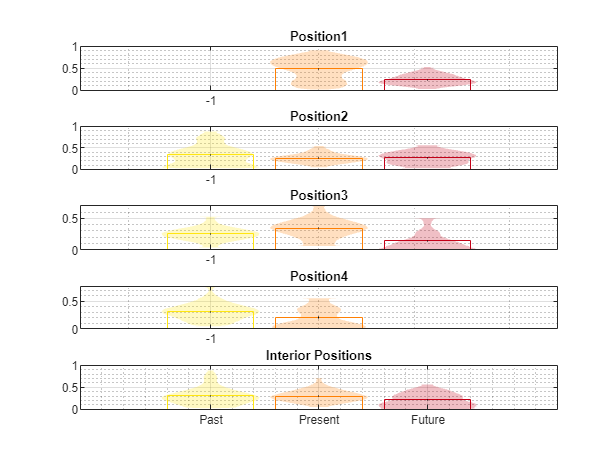

curTst = trInt_TstTrl;
curTst = trIntCON_TstTrl;
figure;
for pos = 1:mlb.seqLength
    subplot(5,1,pos);
    curPos_TstTrl = cell2mat(curTst(pos,:));
    mlb.PlotMeanVarViolin(-1,curPos_TstTrl(1,:),2,0.05,mlb.PPFcolors(1,:));
    mlb.PlotMeanVarViolin(0,curPos_TstTrl(2,:),2,0.05,mlb.PPFcolors(2,:));
    mlb.PlotMeanVarViolin(1,curPos_TstTrl(3,:),2,0.05,mlb.PPFcolors(3,:));
    title(sprintf('Position%i',pos));
    grid on;
    grid minor;
end
tempTest = curTst;
tit = 'All Trials';
tempTest([1,mlb.seqLength],:) = []; tit = 'Interior Positions';
subplot(5,1,5)
curTest = cell2mat(reshape(tempTest,[1,numel(tempTest)]));
mlb.PlotMeanVarViolin(-1,curTest(1,:),2,0.05,mlb.PPFcolors(1,:));
mlb.PlotMeanVarViolin(0,curTest(2,:),2,0.05,mlb.PPFcolors(2,:));
mlb.PlotMeanVarViolin(1,curTest(3,:),2,0.05,mlb.PPFcolors(3,:));
title(tit);
set(gca,'xtick', -1:1, 'xticklabels', [{'Past'}, {'Present'}, {'Future'}]);
grid on;
grid minor;

## Plot Interval Training - Pre-Trial Decoding Post-Trial vice versa

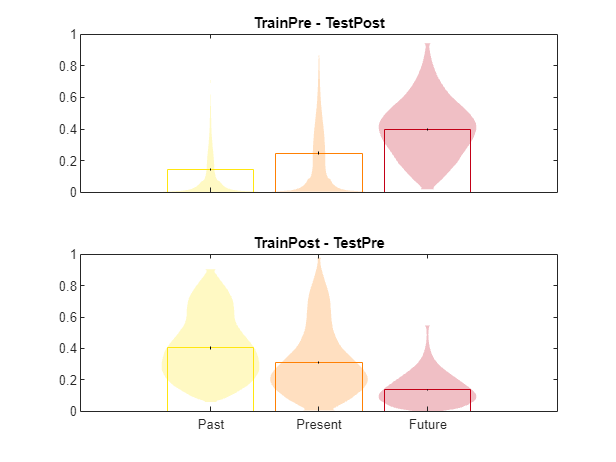

curPrePst = trPre_DecPst;
% curPrePst([1,mlb.seqLength],:) = []; 
curPrePst = cell2mat(curPrePst(:)');
curPstPre = trPst_DecPre;
% curPstPre([1,mlb.seqLength],:) = []; 
curPstPre = cell2mat(curPstPre(:)');

figure; 
subplot(2,1,1)
mlb.PlotMeanVarViolin(-1,curPrePst(1,:),2,0.05,mlb.PPFcolors(1,:));
mlb.PlotMeanVarViolin(0,curPrePst(2,:),2,0.05,mlb.PPFcolors(2,:));
mlb.PlotMeanVarViolin(1,curPrePst(3,:),2,0.05,mlb.PPFcolors(3,:));
title('TrainPre - TestPost');
set(gca,'xticklabels', []);
subplot(2,1,2)
mlb.PlotMeanVarViolin(-1,curPstPre(1,:),2,0.05,mlb.PPFcolors(1,:));
mlb.PlotMeanVarViolin(0,curPstPre(2,:),2,0.05,mlb.PPFcolors(2,:));
mlb.PlotMeanVarViolin(1,curPstPre(3,:),2,0.05,mlb.PPFcolors(3,:));
title('TrainPost - TestPre');
set(gca,'xtick', -1:1, 'xticklabels', [{'Past'}, {'Present'}, {'Future'}]);

## Plot Trial Training - Decode Past/Present/Future

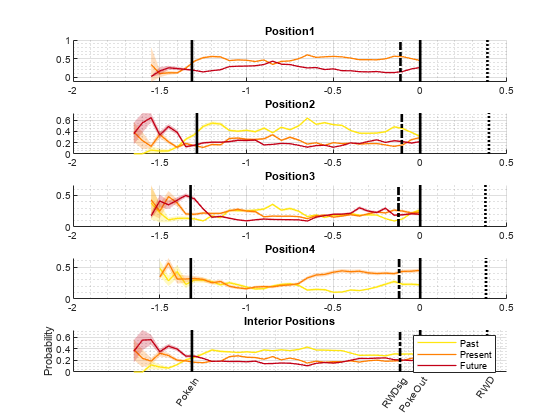

cur_Dec = trTrl_DecPPF;
cur_Dec = trTrl_DecPPFcon;

if strcmp(alignment{1}, 'PokeIn')
    xVals = objTimeVect;
elseif strcmp(alignment{1}, 'RewardSignal') || strcmp(alignment{1}, 'PokeOut') || strcmp(alignment{1}, 'FrontReward')
    switch endTrialBound
        case 'RS'
            xVals = objTimeVect-objTimeVect(end) + median(cell2mat(trialSIGlat(:)'));
        case 'PO'
            xVals = objTimeVect-objTimeVect(end) + median(cell2mat(trialPOlat(:)'));
        case 'RWD'
            xVals = objTimeVect-objTimeVect(end) + median(cell2mat(trialRWDlat(:)'));
    end
end

figure;
sps = nan(1,mlb.seqLength+1);
for pos = 1:mlb.seqLength
    curPos_IntPPF = cell2mat(cur_Dec(pos,:));
    sps(pos) = subplot(mlb.seqLength+1,1,pos);
    mlb.PlotMeanVarLine(xVals, curPos_IntPPF(:,:,1), 2, 0, mlb.PPFcolors(1,:));
    mlb.PlotMeanVarLine(xVals, curPos_IntPPF(:,:,2), 2, 0, mlb.PPFcolors(2,:));
    mlb.PlotMeanVarLine(xVals, curPos_IntPPF(:,:,3), 2, 0, mlb.PPFcolors(3,:));
    plot(repmat(median(cell2mat(lat_TrlStart(pos,:))), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_RwdSig(pos,:))), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_TrlEnd(pos,:))), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_Rwd(pos,:))), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
    title(sprintf('Position%i',pos));
    grid on;
    grid minor;
end

temp_Dec = cur_Dec;
% tit = 'All Trials';
temp_Dec([1,mlb.seqLength],:) = []; tit = 'Interior Positions';
temp_Dec = cell2mat(temp_Dec(:)');
p=nan(1,3);
sps(end) = subplot(mlb.seqLength+1,1,mlb.seqLength+1);
p(1) = mlb.PlotMeanVarLine(xVals, temp_Dec(:,:,1), 2, 0, mlb.PPFcolors(1,:));
p(2) = mlb.PlotMeanVarLine(xVals, temp_Dec(:,:,2), 2, 0, mlb.PPFcolors(2,:));
p(3) = mlb.PlotMeanVarLine(xVals, temp_Dec(:,:,3), 2, 0, mlb.PPFcolors(3,:));
plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
set(gca,'xtick', [median(cell2mat(trialPIlat(:)')),...
    median(cell2mat(trialSIGlat(:)')),...
    median(cell2mat(trialPOlat(:)')),...
    median(cell2mat(trialRWDlat(:)'))], 'xticklabels', [{'PokeIn'}, {'RWDsig'}, {'PokeOut'}, {'RWD'}], 'Xticklabelrotation',55);
title(tit);
legend(p, [{'Past'}, {'Present'}, {'Future'}]);
ylabel('Probability');
grid on;
grid minor;
linkaxes(sps,'x');

## Plot Trial Training - Decode Pre-trial vs Post-Trial

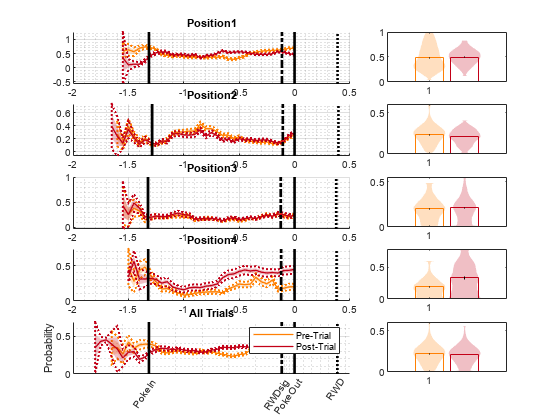

cur_DecInt = trTrl_DecInt; cur_TstInt = trTrl_TstInt;
cur_DecInt = trTrl_DecIntCON; cur_TstInt = trTrl_TstIntCON;

figure;
spNdxs = reshape(1:(mlb.seqLength+1)*3, [3,mlb.seqLength+1])';
sps = nan(2,mlb.seqLength+1);
for pos = 1:mlb.seqLength
    curPos_DecInt = cell2mat(cur_DecInt(pos,:));
    sps(1,pos) = subplot(mlb.seqLength+1,3,spNdxs(pos,1:2));
    mlb.PlotMeanVarLine(xVals, curPos_DecInt(:,:,1), 2, 0.05, mlb.PPFcolors(2,:));
    mlb.PlotMeanVarLine(xVals, curPos_DecInt(:,:,2), 2, 0.05, mlb.PPFcolors(3,:));
    plot(repmat(median(cell2mat(lat_TrlStart(pos,:))), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_RwdSig(pos,:))), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_TrlEnd(pos,:))), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(lat_Rwd(pos,:))), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
    title(sprintf('Position%i',pos));
    grid on;
    grid minor;

    curPos_TstInt = cell2mat(cur_TstInt(pos,:));
    subplot(mlb.seqLength+1,3,spNdxs(pos,3));
    mlb.PlotMeanVarViolin(1, curPos_TstInt(1,:), 2, 0.05, mlb.PPFcolors(2,:));
    mlb.PlotMeanVarViolin(2, curPos_TstInt(2,:), 2, 0.05, mlb.PPFcolors(3,:));
end

temp_DecInt = cur_DecInt;
tit = 'All Trials';
% temp_DecInt([1,mlb.seqLength],:) = []; tit = 'Interior Positions';
% temp_DecInt([mlb.seqLength],:) = []; tit = 'Not Term';
temp_DecInt = cell2mat(temp_DecInt(:)');
p=nan(1,2);
sps(1,end) = subplot(mlb.seqLength+1,3,spNdxs(mlb.seqLength+1,1:2));
p(1) = mlb.PlotMeanVarLine(xVals, temp_DecInt(:,:,1), 2, 0.05, mlb.PPFcolors(2,:));
p(2) = mlb.PlotMeanVarLine(xVals, temp_DecInt(:,:,2), 2, 0.05, mlb.PPFcolors(3,:));
plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
set(gca,'xtick', [median(cell2mat(trialPIlat(:)')),...
    median(cell2mat(trialSIGlat(:)')),...
    median(cell2mat(trialPOlat(:)')),...
    median(cell2mat(trialRWDlat(:)'))], 'xticklabels', [{'PokeIn'}, {'RWDsig'}, {'PokeOut'}, {'RWD'}], 'Xticklabelrotation',55);
title(tit);
legend(p, [{'Pre-Trial'},{'Post-Trial'}]);
ylabel('Probability');
grid on;
grid minor;


temp_TstInt = cur_TstInt;
tit = 'All Trials';
temp_TstInt([1,mlb.seqLength],:) = []; tit = 'Interior Positions';
% temp_TstInt([mlb.seqLength],:) = []; tit = 'Not Term';
temp_TstInt = cell2mat(temp_TstInt(:)');
subplot(mlb.seqLength+1,3,spNdxs(mlb.seqLength+1,3));
mlb.PlotMeanVarViolin(1, temp_TstInt(1,:), 2, 0.05, mlb.PPFcolors(2,:));
mlb.PlotMeanVarViolin(2, temp_TstInt(2,:), 2, 0.05, mlb.PPFcolors(3,:));
linkaxes(sps,'x');

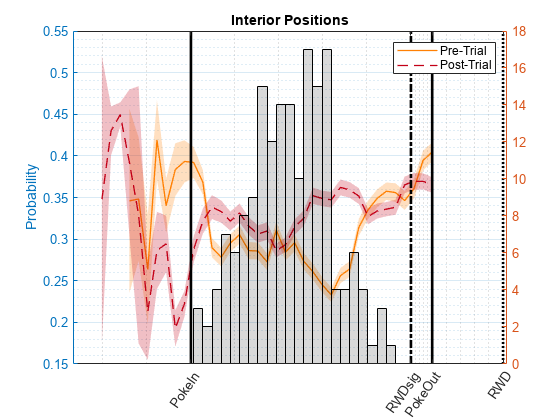

figure
yyaxis right
histogram(outSeqPokeDurs+median(cell2mat(trialPIlat(:)')), mlb.obsvTimeVect(trWinLog), 'FaceColor', 'k', 'FaceAlpha', 0.15);
yyaxis left
p(1) = mlb.PlotMeanVarLine(xVals, temp_DecInt(:,:,1), 2, 0, mlb.PPFcolors(2,:));
p(2) = mlb.PlotMeanVarLine(xVals, temp_DecInt(:,:,2), 2, 0, mlb.PPFcolors(3,:));
plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
set(gca,'xtick', [median(cell2mat(trialPIlat(:)')),...
    median(cell2mat(trialSIGlat(:)')),...
    median(cell2mat(trialPOlat(:)')),...
    median(cell2mat(trialRWDlat(:)'))], 'xticklabels', [{'PokeIn'}, {'RWDsig'}, {'PokeOut'}, {'RWD'}], 'Xticklabelrotation',55);
title(tit);
legend(p, [{'Pre-Trial'},{'Post-Trial'}]);
ylabel('Probability');
grid on;
grid minor;